### **1. Set up the Project.**

Creating the necessairy directories and loading the names used to run the project.

The program then asks for the person's first name as well as the letter (vowel) they are going to record.

% Directories used in this project
result_directory_name = "result_dir\";

% Check if the audiofiles directory exists
if ~isfolder(result_directory_name)
    mkdir(result_directory_name);
    fprintf('Directory "%s" created.\n', result_directory_name);
else
    fprintf('Directory "%s" already exists.\n', result_directory_name);
end

Directory "result_dir\" already exists.


### **2. Record data and store it in a .m4a file.**

**Connect the Microphone.**

Fs = 48000; % Sampling Frequency
recObj = audiorecorder(Fs,16,1,1);

**Setup file names**

person_name = input('Enter your name: ', 's');
audiofile_name = result_directory_name + person_name + ".m4a";
spectrogramfile_name = result_directory_name + person_name + ".png";
for i = 3:-1:1
    disp(i)
    pause(1)
end

     3

     2

     1



clear i; 

**Record voice.**

recDuration = 1;
disp("Begin speaking.")

Begin speaking.


recordblocking(recObj,recDuration)
disp("End of recording.")

End of recording.


y = getaudiodata(recObj);
clear recDuration; clear recObj;

**Cut and save the recording.**

x = y(2.3e4:4.5e4, 1);
audiowrite(audiofile_name, x, Fs);
disp("audiofile saved successfully!")

audiofile saved successfully!


clear y; clear x; clear Fs;

**Compute FFT and spectogram.**

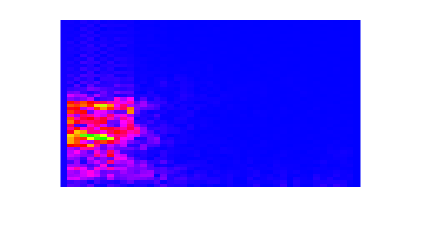

x = audioread(audiofile_name);              % audiofile
step_size = 500;                            % Amount of audio file readings per column
sample_size = 1000;                         % Amount of FFT samples (does NOT increase resolution!) >= step_size
M = FFT_Matrix(x,sample_size,step_size);
MC = FFT_Spectogram(M(1:50,:),40,10,5);  % over 50 on y-axis the amplitude is insigificantly low
img = flip(MC,1);                           % Origin (0,0) is bottom left corner
imshow(img);

imwrite(img,spectrogramfile_name)
disp("spectrogramfile saved successfully!")

spectrogramfile saved successfully!


clear x; clear M; clear freq; clear MC; clear img; clear step_size; clear sample_size;
clear audiofile_name; 

### **Generate two spectograms and compare them using SSIM, PSNR and MSE**

% https://ch.mathworks.com/matlabcentral/answers/1915530-how-to-create-4d-array-of-images?#answer_1176085
List_of_files  = dir(fullfile('spectrogramfiles_lib\', '*.png'));
List_of_matches = {};
for a = 1:numel(List_of_files)
    % Get library spectogram and its name
    lib_image = imread(fullfile(List_of_files(a).folder, List_of_files(a).name));
    if contains(List_of_files(a).name(), person_name, 'IgnoreCase', true)
        Letter = List_of_files(a).name(end-4)
        comparison_image = imread(spectrogramfile_name, "png");
        
        ssimval = ssim(lib_image, comparison_image) 
        peaksnr = psnr(lib_image, comparison_image) 
        MSE_err = immse(lib_image, comparison_image) 

        matching_score = ssimval * 100;
        %disp(Letter + matching_score);
        % Store result in a list
        List_of_matches = [List_of_matches; {Letter, matching_score}];
    end
end

Letter = 'A'

ssimval = 0.6652

peaksnr = 8.7734

MSE_err = 8.6246e+03

Letter = 'B'

ssimval = 0.7705

peaksnr = 10.6371

MSE_err = 5.6152e+03

Letter = 'C'

ssimval = 0.8155

peaksnr = 11.7366

MSE_err = 4.3594e+03

Letter = 'D'

ssimval = 0.8064

peaksnr = 11.5731

MSE_err = 4.5265e+03

Letter = 'E'

ssimval = 0.7028

peaksnr = 9.2655

MSE_err = 7.7007e+03

Letter = 'F'

ssimval = 0.9089

peaksnr = 14.6621

MSE_err = 2.2227e+03

Letter = 'G'

ssimval = 0.8079

peaksnr = 11.3099

MSE_err = 4.8094e+03

Letter = 'H'

ssimval = 0.6837

peaksnr = 9.0673

MSE_err = 8.0604e+03

Letter = 'I'

ssimval = 0.7721

peaksnr = 10.4371

MSE_err = 5.8799e+03

Letter = 'J'

ssimval = 0.8338

peaksnr = 11.9322

MSE_err = 4.1674e+03

Letter = 'K'

ssimval = 0.7594

peaksnr = 10.4753

MSE_err = 5.8285e+03

Letter = 'L'

ssimval = 0.6550

peaksnr = 8.6392

MSE_err = 8.8954e+03

Letter = 'M'

ssimval = 0.8216

peaksnr = 11.8696

MSE_err = 4.2279e+03

Letter = 'N'

ssimval = 0.7579

peaksnr = 10.3268

MSE_err = 6.0312e+03

Letter = 'O'

ssimval = 0.7621

peaksnr = 10.3187

MSE_err = 6.0424e+03

Letter = 'P'

ssimval = 0.8023

peaksnr = 11.4844

MSE_err = 4.6200e+03

Letter = 'Q'

ssimval = 0.7874

peaksnr = 10.7580

MSE_err = 5.4611e+03

Letter = 'R'

ssimval = 0.9183

peaksnr = 15.1058

MSE_err = 2.0068e+03

Letter = 'S'

ssimval = 0.8014

peaksnr = 11.0429

MSE_err = 5.1144e+03

Letter = 'T'

ssimval = 0.8662

peaksnr = 13.2413

MSE_err = 3.0828e+03

Letter = 'U'

ssimval = 0.8149

peaksnr = 11.4981

MSE_err = 4.6055e+03

Letter = 'V'

ssimval = 0.7822

peaksnr = 10.5294

MSE_err = 5.7563e+03

Letter = 'W'

ssimval = 0.8907

peaksnr = 13.9862

MSE_err = 2.5969e+03

Letter = 'X'

ssimval = 0.9038

peaksnr = 14.4585

MSE_err = 2.3293e+03

Letter = 'Y'

ssimval = 0.7158

peaksnr = 9.5305

MSE_err = 7.2449e+03

Letter = 'Z'

ssimval = 0.9255

peaksnr = 15.9667

MSE_err = 1.6459e+03

clear a;

highestValue = 0;
% Loop through the list of pairs to find the highest value
for i = 1:size(List_of_matches,1)
    % Get the current value
    currentValue = List_of_matches{i,2};
    
    % Check if the current value is higher than the highest value found so far
    if currentValue > highestValue
        highestValue = currentValue;
        highestValueIndex = i;
    end
end
disp(person_name + ", you said the letter: " + List_of_matches{highestValueIndex,1})

Silvan, you said the letter: Z


clear all;

## Our own functions

### Linear colour gradient

(basic principle)

function result = linear_gradient(val,period,type_size)
    val_mod = mod(val,(6*period));

    if (0 <= val_mod) && (val_mod < period)
        result = (type_size*val_mod)/period;

    elseif (period <= val_mod) && (val_mod < 3*period)
        result = type_size;

    elseif (3*period <= val_mod) && (val_mod < 4*period)
        result = (type_size-(type_size*((val_mod+1)-4*period)))/period;

    elseif (4*period <= val_mod) && (val_mod < 6*period)
        result = 0;

    end
end

### Convert amplitude to colour

blue at amp = 0 and cyan at amp = max, if larger then max goes back to blue 

function result = double2rgb(amp,max)
    spec = [0 0 0];
    period = max/5;
    type_size = 1;      % double = 1 , uint8 = 255
    
    spec(1) = linear_gradient(amp,            period, type_size);
    spec(2) = linear_gradient(amp + 4*period, period, type_size);
    spec(3) = linear_gradient(amp + 2*period, period, type_size);

    result = spec;
end

### FFT in timeintervals saved in matrix

y-axis : frequency

x-axis : time

function M = FFT_Matrix(Signal,sample_size,step_size)

    Xb(1:sample_size ,1) = 0;
    M(1:((sample_size/2)+1),1:round(size(Signal)/step_size)) = -1;
    
    for n = 1:round(size(Signal)/step_size)
    step = (n-1) * step_size;
    Xb(1:step_size,1) = Signal(step+1:step+step_size,1);    %isolate the amount(step_size) of audio readings rest is filled with 0
    Yb = fft(Xb);                                           %convert step_size(timeinterval) with fft
    M(1:((sample_size/2)+1),n) = abs(Yb(1:((sample_size/2)+1)));    %save only half of the calculated values, fourie spectrum in mirrored after the first half
    end
end

#### FFT_Matrix converted to spectogram

function MC = FFT_Spectogram(FFT_Matrix,Max_Amp,sizeX,sizeY)

    MC(1:size(FFT_Matrix,1)*sizeY,1:size(FFT_Matrix,2)*sizeX,1:3) = -1;
    Colour(1:3) = -1;
    for n = 0:size(FFT_Matrix,1)-1
        for m = 0:size(FFT_Matrix,2)-1
            Colour(1:3) = double2rgb(FFT_Matrix(n+1,m+1),Max_Amp);  %calculate colour
            % create a sizeX*sizeY rectangle of this colour
            MC((n*sizeY:(n*sizeY)+sizeY)+1,(m*sizeX:(m*sizeX)+sizeX)+1,1) = Colour(1);
            MC((n*sizeY:(n*sizeY)+sizeY)+1,(m*sizeX:(m*sizeX)+sizeX)+1,2) = Colour(2);
            MC((n*sizeY:(n*sizeY)+sizeY)+1,(m*sizeX:(m*sizeX)+sizeX)+1,3) = Colour(3);
        end
    end
end
